# Single Parameter Wavelet Based Local Contrast Enhancement

**parameter: intensity of enhancement**

**offset: brightness added or reduced**

**CLAHE optional**

clear; clc; close all;



parameter = 2.5;

brightness = 0;

CLAHE = false;

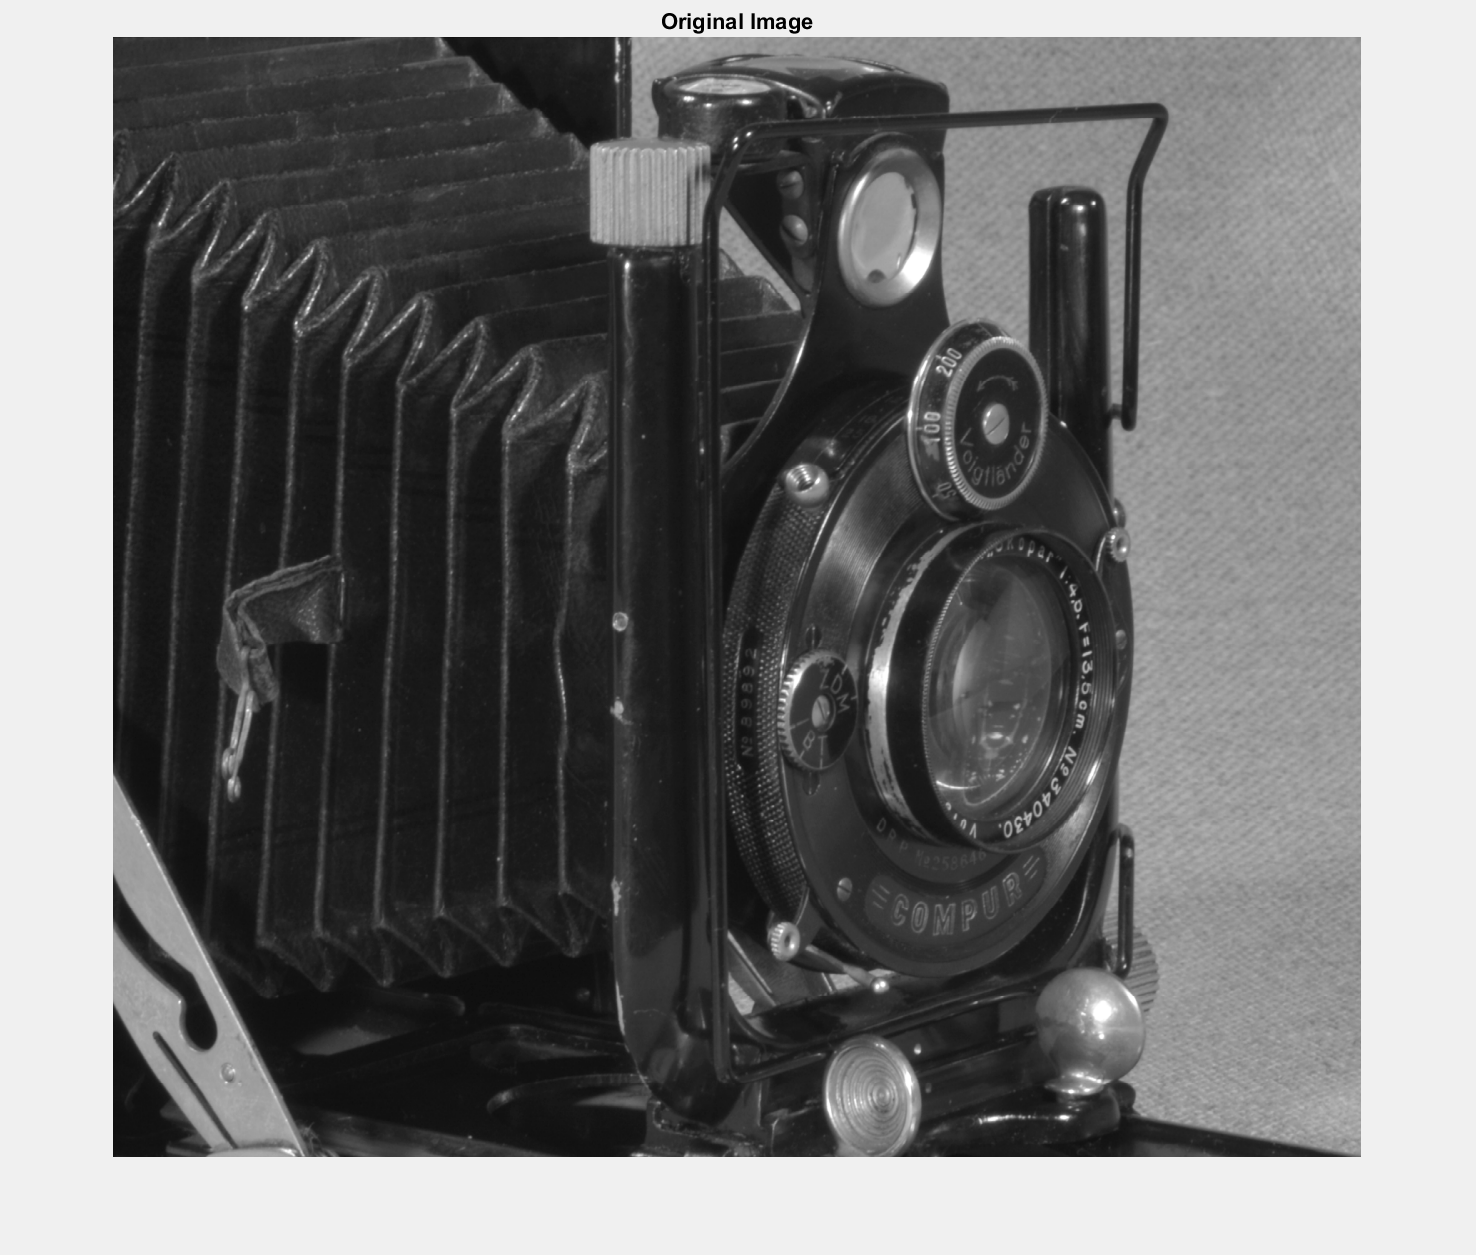

 

file_path = 'E:\github\Image processing class and project\Course project\Wavelet-Based Local Contrast Enhancement for Satellite, Aerial and Close Range Images\image2.bmp';

image_original = imread(file_path);
[h, w, ~] = size(image_original);
if ~CLAHE
    image = rgb2gray(image_original(1:h-mod(h,16), 1:w-mod(w,16), :));
else
    image = adapthisteq(rgb2gray(image_original(1:h-mod(h,16), 1:w-mod(w,16), :)));
end
image_denoised = wdenoise2(image, 'DenoisingMethod', 'SURE');

[A,H,V,D] = swt2(image_denoised,4,'haar');
cutoff = my_iswt2_second(A,H,V,D, 'haar');
my_sigma = cutoff./3;
g = [1 1 1 1].*[parameter parameter+1 parameter+0.5 parameter].* my_sigma .*2.5;

enhanced = my_iswt2(A,H,V,D, 'haar', my_sigma, g) + brightness;

fig1 = figure;
set(gcf,'Visible','on')
% fig1.Position(3:4) = [w, h];
imshow(uint8(rgb2gray(image_original(1:h-mod(h,16), 1:w-mod(w,16), :))), [0 255])
title('Original Image')

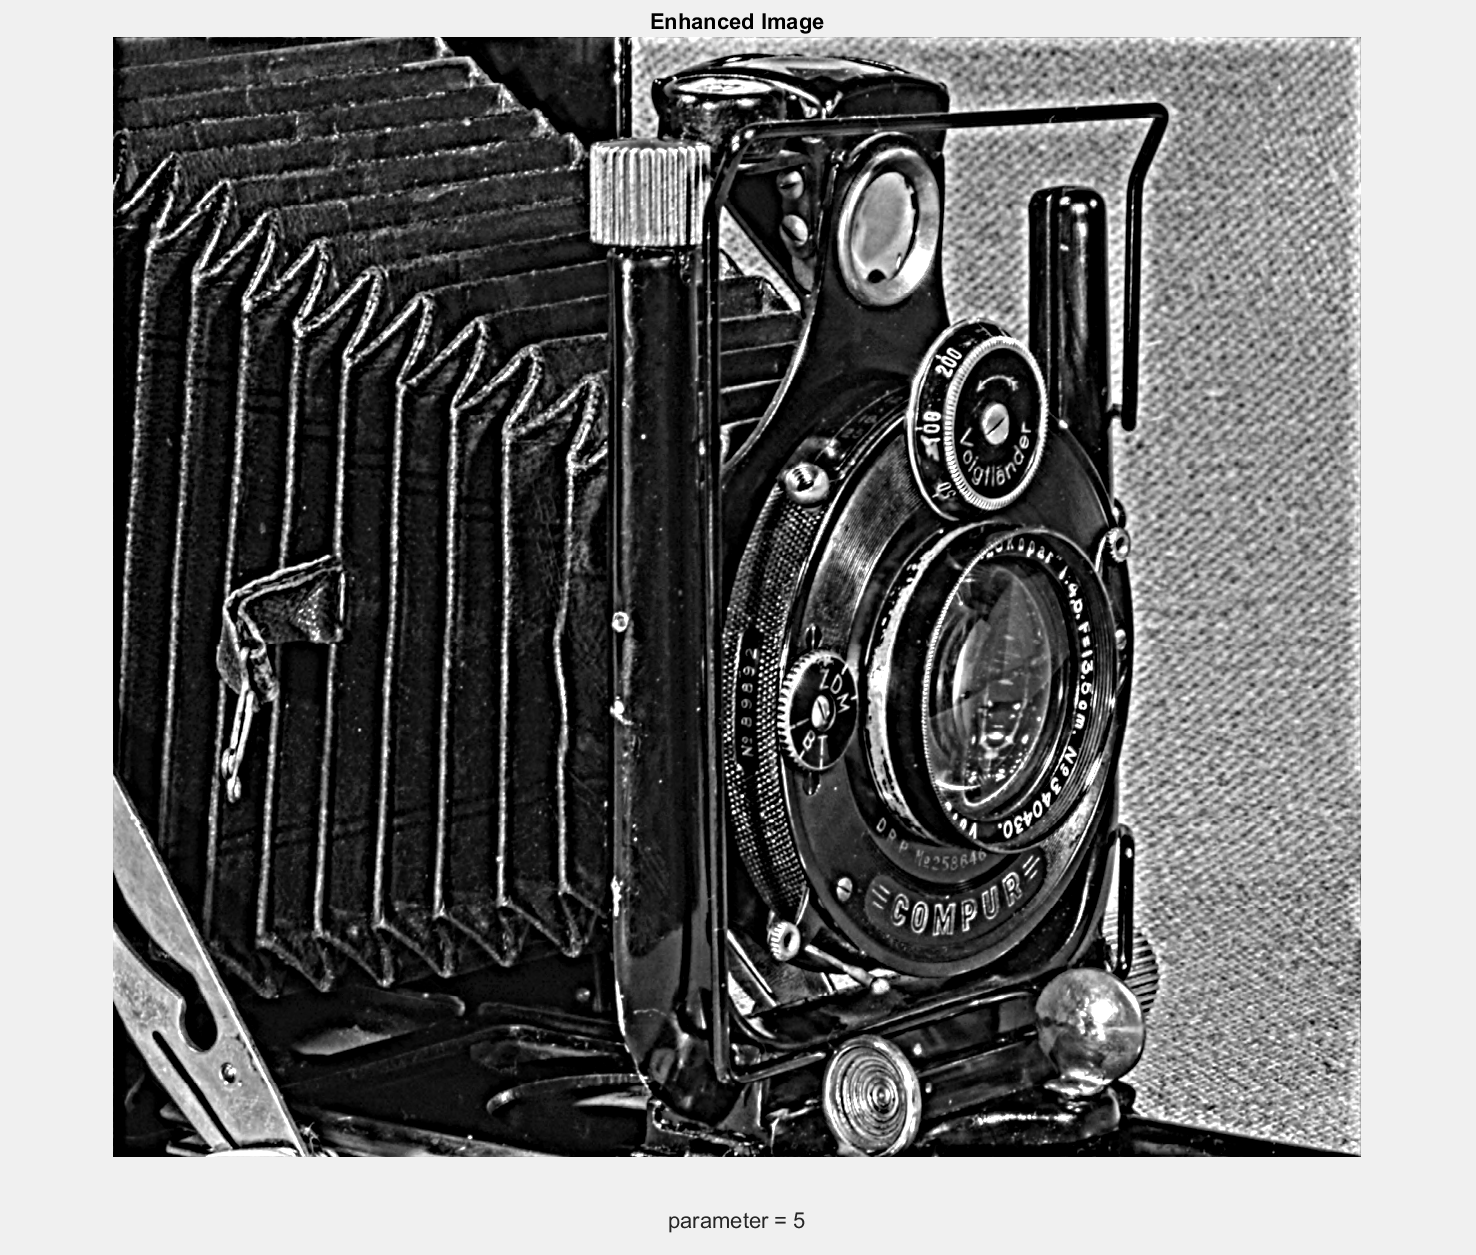


fig2 = figure;
set(gcf,'Visible','on')
% fig2.Position(3:4) = [w-mod(w,16), h-mod(h,16)];
imshow(uint8(enhanced), [0 255])
title('Enhanced Image')
xlabel(['parameter = ' num2str(parameter)])